# TP 5 - Motion analysis - Lucas and Kanade

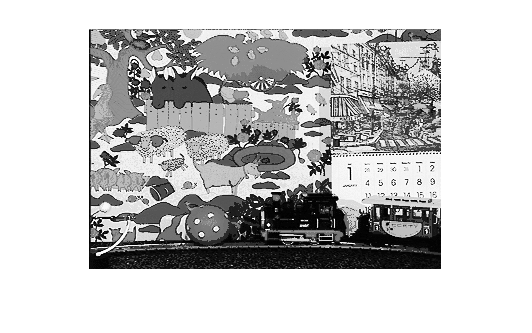

im1=imread('TP06I01.bmp');
im2=imread('TP06I02.bmp');
imshow(im1)

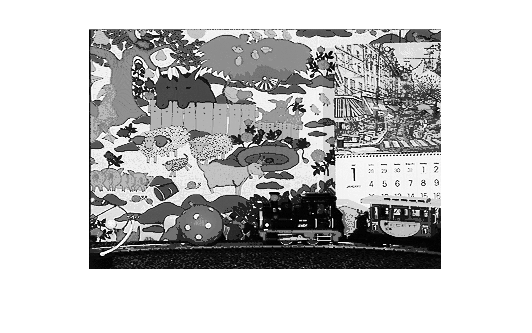

imshow(im2)

im1=double(im1);
im2=double(im2);

[x,y]=size(im1)

x = 240

y = 352

for i=2:x-1
    for j=2:y-1
        add1=(im1(i-1,j-1)-im1(i,j-1))^2;
        add2=(im1(i,j-1)-im1(i+1,j-1))^2;
        add3=(im1(i-1,j)-im1(i,j))^2;
        add4=(im1(i,j)-im1(i+1,j))^2;
        add5=(im1(i-1,j+1)-im1(i,j+1))^2;
        add6=(im1(i,j+1)-im1(i+1,j+1))^2;
        dx(i,j)=add1+add2+add3+add4+add5+add6;
        
        add1=(im1(i-1,j-1)-im1(i-1,j))^2;
        add2=(im1(i-1,j)-im1(i-1,j+1))^2;
        add3=(im1(i,j-1)-im1(i,j))^2;
        add4=(im1(i,j)-im1(i,j+1))^2;
        add5=(im1(i+1,j-1)-im1(i+1,j))^2;
        add6=(im1(i+1,j)-im1(i+1,j+1))^2;
        dy(i,j)=add1+add2+add3+add4+add5+add6;
        
        add1=im1(i-1,j-1)-im1(i,j);
        add2=im1(i,j)-im1(i+1,j+1);
        add3=im1(i-1,j)-im1(i,j+1);
        add4=im1(i,j-1)-im1(i+1,j);
        dxy(i,j)=add1+add2+add3+add4;
        
    end
end

